clearvars

%Setup
addpath(pwd);
[status,pyver]=system('python --version');
if status==0
    fprintf('Python: %s\n',strtrim(pyver)); 
end

Python: Python 3.12.10



%Image Generation
tic
prompt='an astronaut watching sunrise and a big planet in the background with mountains';
steps=28;
seed=42;
model_id='runwayml/stable-diffusion-v1-5';
output_filename='generated.png';
cmd=sprintf('python generate_image.py --prompt "%s" --steps %d --seed %d --model "%s" --out "%s"', ...
    prompt, steps, seed, model_id, output_filename);
fprintf('Running: %s\n', cmd);

Running: python generate_image.py --prompt "an astronaut watching sunrise and a big planet in the background with mountains" --steps 28 --seed 42 --model "runwayml/stable-diffusion-v1-5" --out "generated.png"


[status,cmdout]=system(cmd);
fprintf('%s\n',cmdout);

Loading pipeline components...:  43%|####2     | 3/7 [00:01<00:01,  2.18it/s]Loading pipeline components...:  57%|#####7    | 4/7 [00:01<00:01,  2.84it/s]Loading pipeline components...:  71%|#######1  | 5/7 [00:01<00:00,  3.24it/s]Loading pipeline components...: 100%|##########| 7/7 [00:01<00:00,  3.80it/s]
Generating with model=StableDiffusionPipeline, device=cuda:0, steps=28
  0%|          | 0/28 [00:00<?, ?it/s]  4%|3         | 1/28 [00:00<00:11,  2.44it/s]  7%|7         | 2/28 [00:00<00:06,  4.20it/s] 11%|#         | 3/28 [00:00<00:04,  5.57it/s] 14%|#4        | 4/28 [00:00<00:03,  6.57it/s] 18%|#7        | 5/28 [00:00<00:03,  7.28it/s] 21%|##1       | 6/28 [00:00<00:02,  7.78it/s] 25%|##5       | 7/28 [00:01<00:02,  8.12it/s] 29%|##8       | 8/28 [00:01<00:02,  8.43it/s] 32%|###2      | 9


if ~exist(output_filename,'file')
    error('Generated image not found');
end
toc

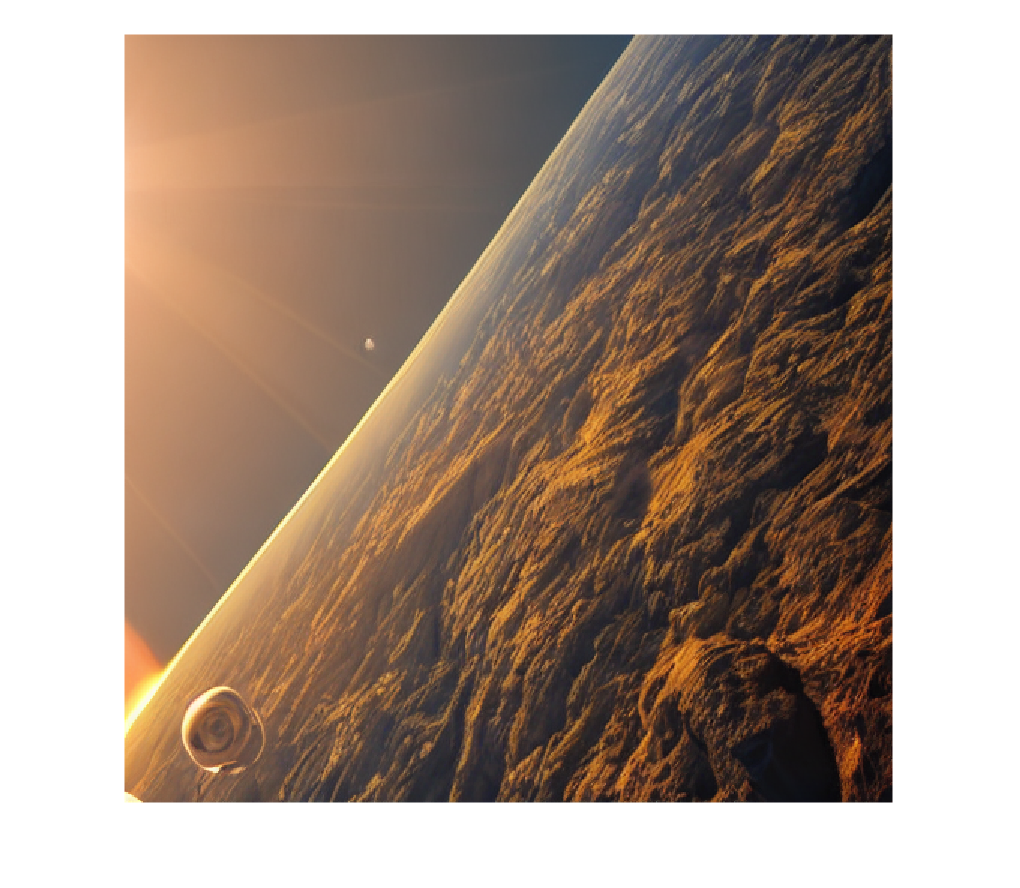

%Load Image
img_orig=im2double(imread(output_filename));
[H, W, C]=size(img_orig);
if C==1 
    img_orig = repmat(img_orig,[1,1,3]); 
end

figure;
imshow(img_orig);

%Parameters 
params=struct();
params.global_scale=1.0;
params.freq_threshold=1;        
params.b1=1;                  
params.b2=1.3;                  
params.s1=2;                  
params.s2=2;                  
params.amplitude_scale=1.0;
params.phase_scale=1.0;
params.blend_type=2; 

%Convert to YCbCr
ycbcr=rgb2ycbcr(img_orig);
Y=ycbcr(:,:,1);
Cb=ycbcr(:,:,2);
Cr=ycbcr(:,:,3);

%Apply DMFFT 
Y_enhanced=fourier(Y,params.global_scale,params.freq_threshold, ...
    params.b1,params.s1,params.amplitude_scale,params.phase_scale,params.blend_type);
Y_final=min(max(Y_enhanced,0),1);

%Reconstruct RGB
img_enhanced=ycbcr2rgb(cat(3, Y_final, Cb, Cr));
img_enhanced=min(max(img_enhanced, 0), 1);

%Save
imwrite(img_enhanced,'dmfft_enhanced.png');
fprintf('Saved: dmfft_enhanced.png\n');

Saved: dmfft_enhanced.png


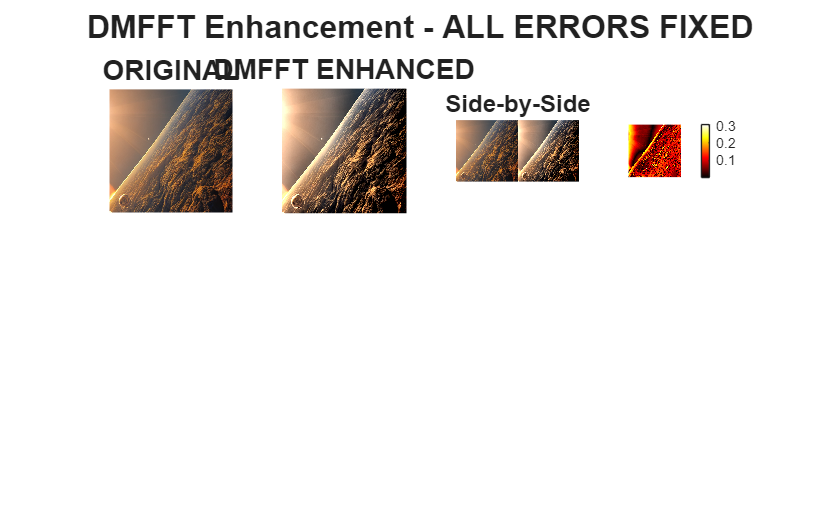

figure;
sgtitle('DMFFT Enhancement - ALL ERRORS FIXED', 'FontSize',16,'FontWeight','bold');

subplot(2,4,1);
imshow(img_orig);
title('ORIGINAL', 'FontSize',14,'FontWeight','bold');

subplot(2,4,2);
imshow(img_enhanced);
title('DMFFT ENHANCED', 'FontSize',14,'FontWeight','bold');

subplot(2,4,3);
imshowpair(img_orig, img_enhanced, 'montage');
title('Side-by-Side', 'FontSize',12);

subplot(2,4,4);
diff = abs(rgb2gray(img_enhanced) - rgb2gray(img_orig));
imagesc(diff); axis image off; colormap(gca,'hot'); colorbar;

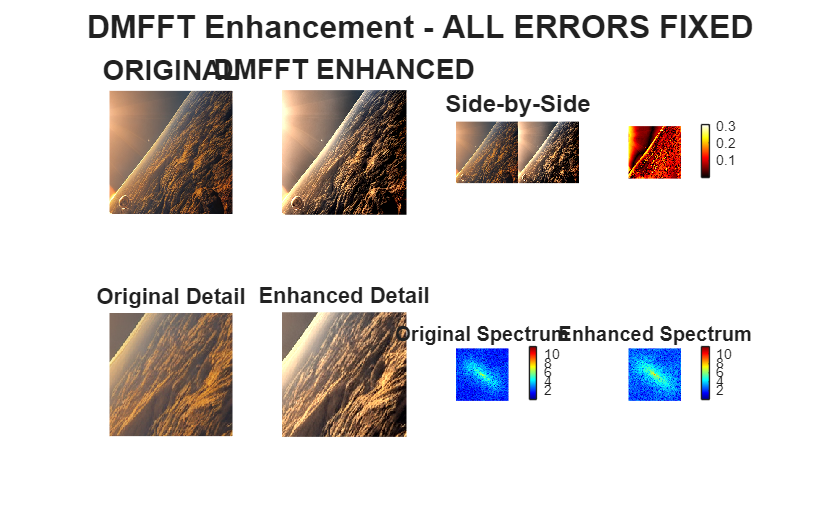

% Details
crop_size=min(256, floor(min(H,W)/3));
cy=floor(H/2)-floor(crop_size/2)+(1:crop_size);
cx=floor(W/2)-floor(crop_size/2)+(1:crop_size);

subplot(2,4,5);
imshow(img_orig(cy,cx,:));
title('Original Detail', 'FontSize',11);

subplot(2,4,6);
imshow(img_enhanced(cy,cx,:));
title('Enhanced Detail', 'FontSize',11);

% Frequency analysis
subplot(2,4,7);
imagesc(log(abs(fftshift(fft2(Y)))+1));
axis image off; colormap(gca,'jet'); colorbar;
title('Original Spectrum', 'FontSize',10);

subplot(2,4,8);
imagesc(log(abs(fftshift(fft2(Y_final)))+1));
axis image off; colormap(gca,'jet'); colorbar;
title('Enhanced Spectrum', 'FontSize',10);

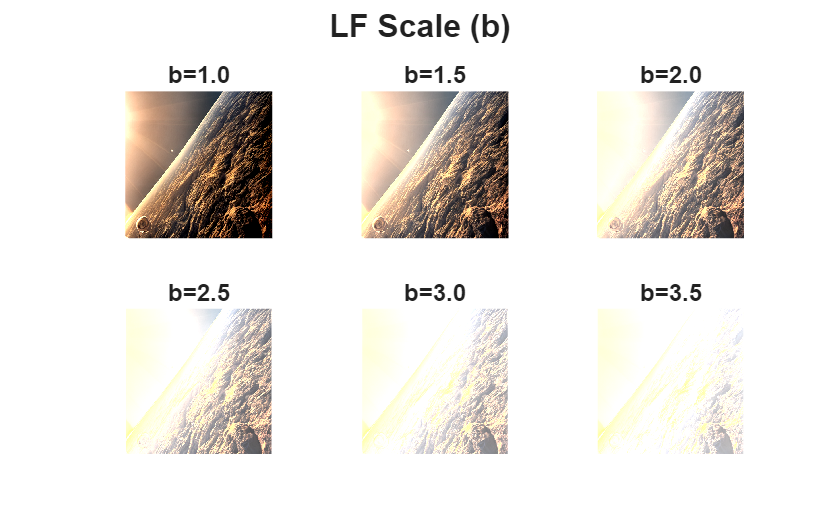

%LF scale
b_values=[1,1.5,2,2.5,3,3.5];
figure
sgtitle('LF Scale (b)', 'FontSize',16,'FontWeight','bold');

for i = 1:length(b_values)
    Y_test=fourier(Y,params.global_scale,params.freq_threshold, ...
        b_values(i),params.s1,params.amplitude_scale,params.phase_scale, params.blend_type);
    Y_test=min(max(Y_test, 0), 1);
    img_test=ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    
    title(sprintf('b=%.1f',b_values(i)),'FontSize',12);
    
end

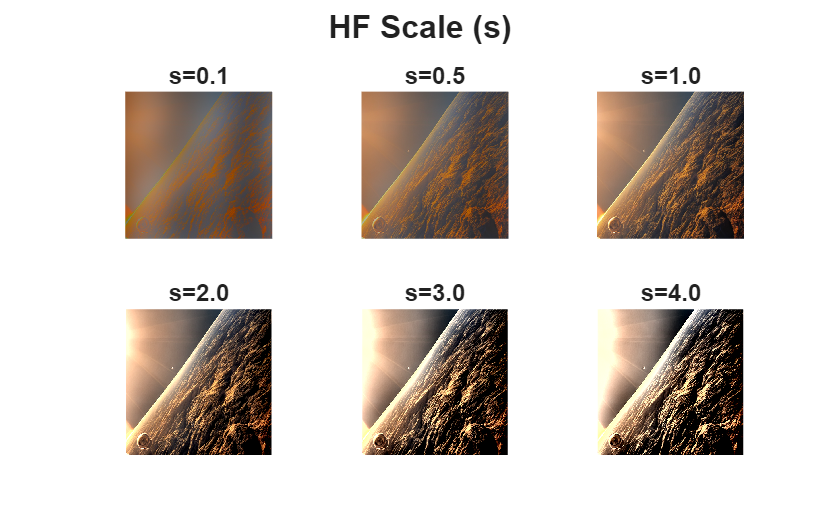

%HF scale
s_values=[0.1,0.5,1,2,3,4];
figure
sgtitle('HF Scale (s)', 'FontSize',16,'FontWeight','bold');

for i=1:length(s_values)
    Y_test=fourier(Y, params.global_scale, params.freq_threshold, ...
        params.b1, s_values(i), params.amplitude_scale, params.phase_scale, params.blend_type);
    Y_test = min(max(Y_test, 0), 1);
    img_test = ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    
    title(sprintf('s=%.1f', s_values(i)), 'FontSize',12);
 
end

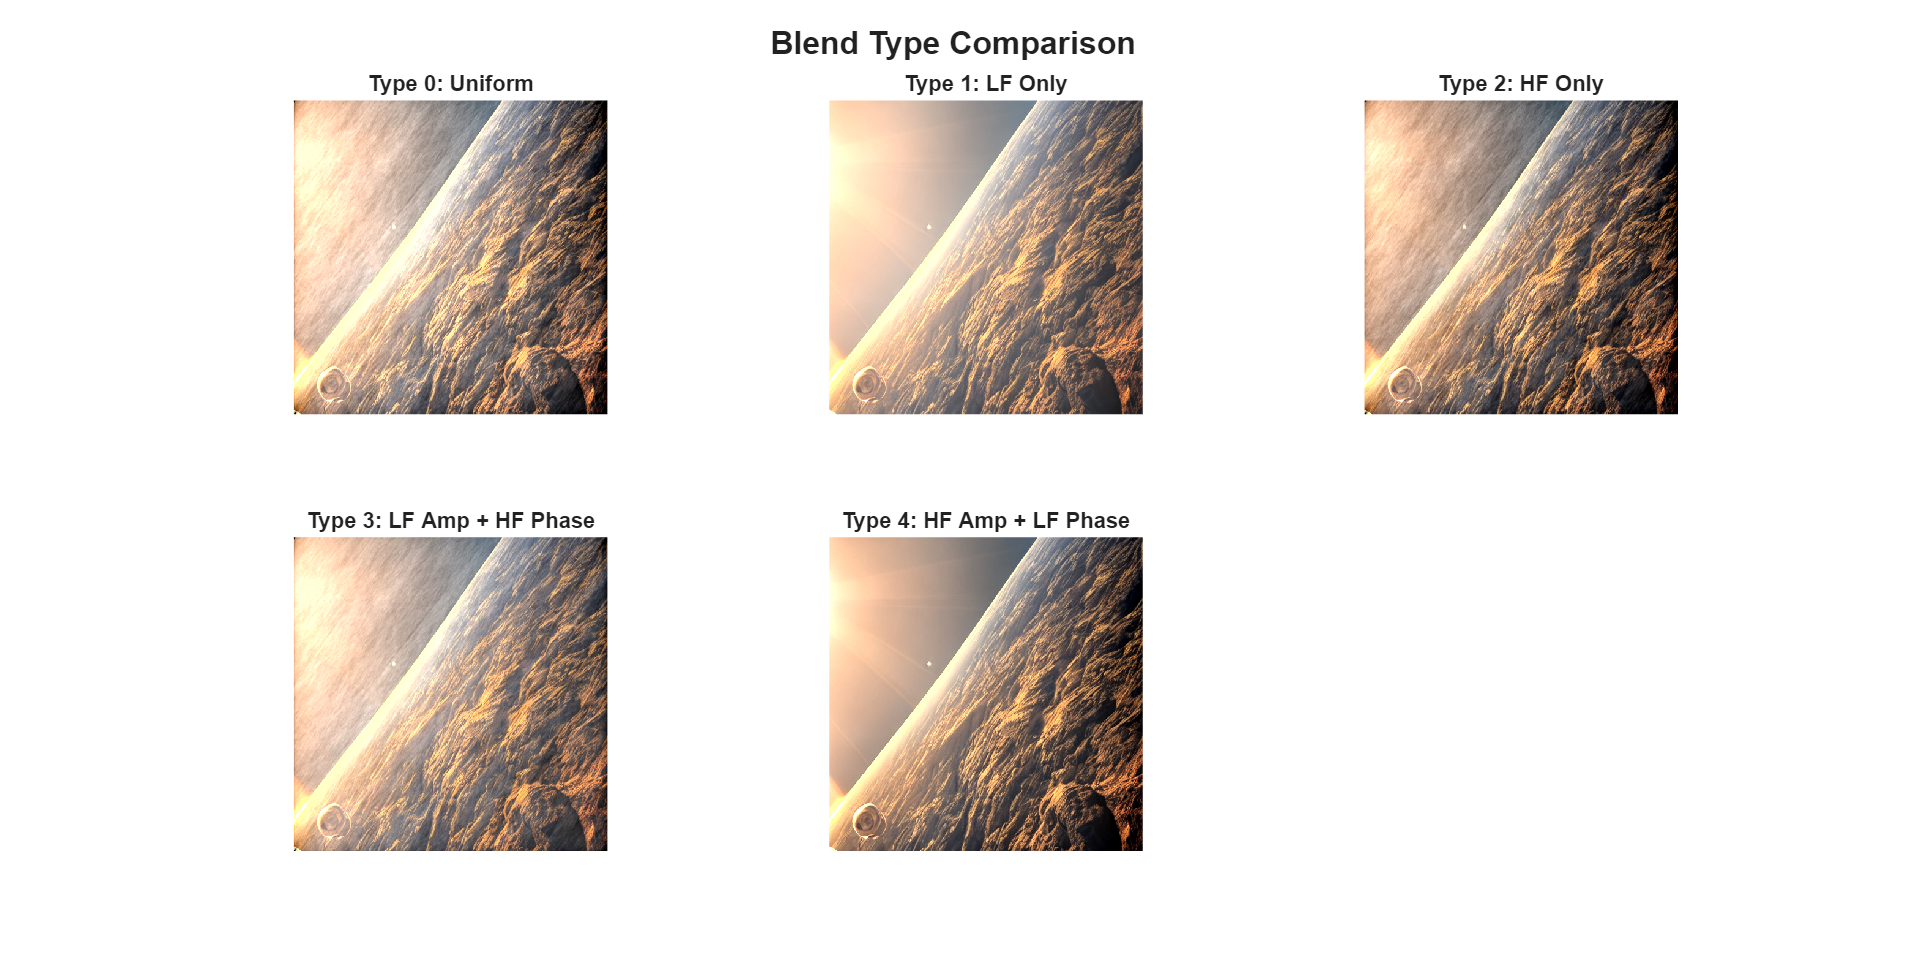

%Blend Type Comparison
blend_types = [0, 1, 2, 3, 4];
blend_names = {'Uniform', 'LF Only', 'HF Only', 'LF Amp + HF Phase', 'HF Amp + LF Phase'};

figure('Color','w','Position',[100 100 1600 800]);
sgtitle('Blend Type Comparison', 'FontSize',16,'FontWeight','bold');

for i = 1:length(blend_types)
    Y_test = fourier(Y, 1.0, 1, 1.3, 1.3, 1.2, 1.2, blend_types(i));
    Y_test = min(max(Y_test, 0), 1);
    img_test = ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    title(sprintf('Type %d: %s', blend_types(i), blend_names{i}), 'FontSize',11);
end

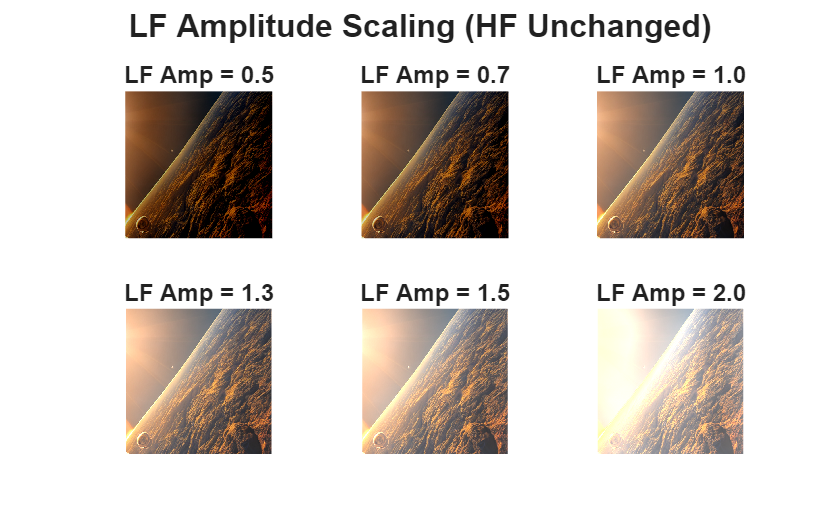

%Amplitude Scaling
amp_values = [0.5, 0.7, 1.0, 1.3, 1.5, 2.0];

figure;
sgtitle('LF Amplitude Scaling (HF Unchanged)', 'FontSize',16,'FontWeight','bold');

for i = 1:length(amp_values)
    Y_test = fourier(Y, 1.0, 1, 1.0, 1.0, amp_values(i), 1.0, 1);
    %                                                    ^^^ amplitude_scale
    Y_test = min(max(Y_test, 0), 1);
    img_test = ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    title(sprintf('LF Amp = %.1f', amp_values(i)), 'FontSize',12);
end

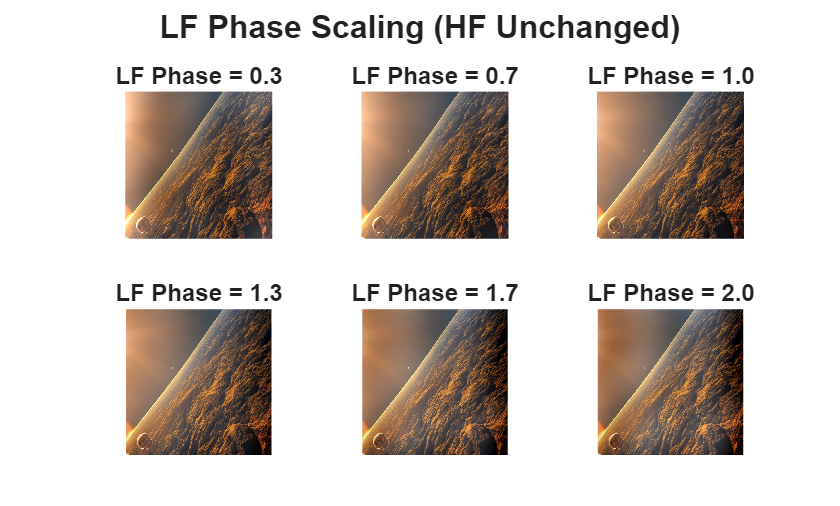


%Phase Scaling 
phase_values = [0.3, 0.7, 1.0, 1.3, 1.7, 2.0];

figure;
sgtitle('LF Phase Scaling (HF Unchanged)', 'FontSize',16,'FontWeight','bold');

for i = 1:length(phase_values)
    Y_test = fourier(Y, 1.0, 1, 1.0, 1.0, 1.0, phase_values(i), 1);
    %                                                         ^^^ phase_scale
    Y_test = min(max(Y_test, 0), 1);
    img_test = ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    title(sprintf('LF Phase = %.1f', phase_values(i)), 'FontSize',12);
end

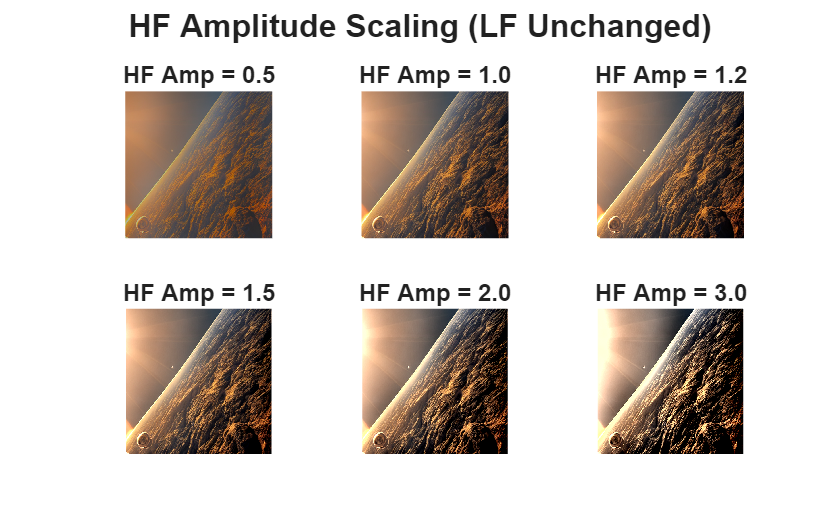

%HF Amplitude Scaling 
hf_amp_values = [0.5, 1.0, 1.2, 1.5, 2.0, 3.0];
figure;
sgtitle('HF Amplitude Scaling (LF Unchanged)', 'FontSize',16,'FontWeight','bold');

for i = 1:length(hf_amp_values)
    Y_test = fourier(Y, 1.0, 1, 1.0, 1.0, hf_amp_values(i), 1.0, 2);
    Y_test = min(max(Y_test, 0), 1);
    img_test = ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    title(sprintf('HF Amp = %.1f', hf_amp_values(i)), 'FontSize',12);
end

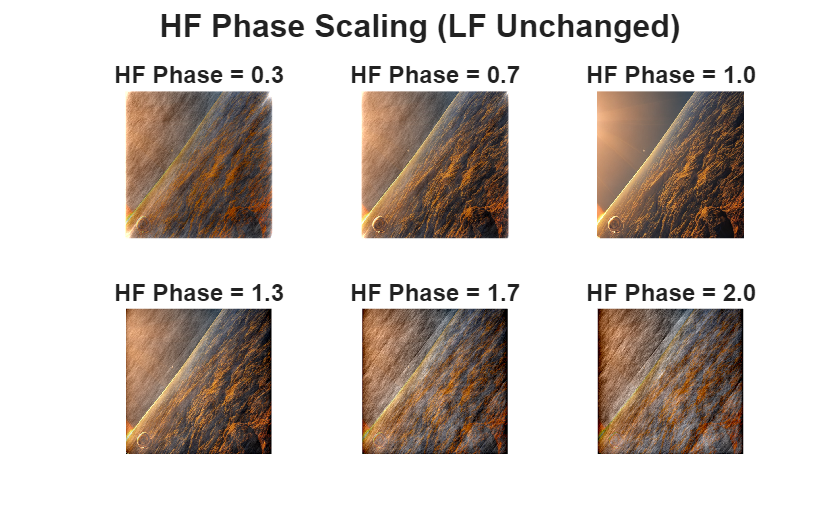


%HF Phase Scaling 
hf_phase_values = [0.3, 0.7, 1.0, 1.3, 1.7, 2.0];
figure;
sgtitle('HF Phase Scaling (LF Unchanged)', 'FontSize',16,'FontWeight','bold');

for i = 1:length(hf_phase_values)
    Y_test = fourier(Y, 1.0, 1, 1.0, 1.0, 1.0, hf_phase_values(i), 2);
    Y_test = min(max(Y_test, 0), 1);
    img_test = ycbcr2rgb(cat(3, Y_test, Cb, Cr));
    
    subplot(2,3,i);
    imshow(img_test);
    title(sprintf('HF Phase = %.1f', hf_phase_values(i)), 'FontSize',12);
end

function x_filtered = fourier(x, global_scale, freq_threshold, lf_scale, hf_scale, ...
                                          amplitude_scale, phase_scale, blend_type)
    
    [H, W] = size(x);
    
    x = x * global_scale;
    
    if blend_type == -1
        x_filtered = x;
        return;
    end
    
    x_freq = fftshift(fft2(x));
    
    mask = ones(H, W) * hf_scale;
    
    % FIXED: Use ceil() to match Python H // 2
    crow = ceil(H / 2);
    ccol = ceil(W / 2);
    
    top = max(1, crow - freq_threshold);
    bottom = min(H, crow + freq_threshold);
    left = max(1, ccol - freq_threshold);
    right = min(W, ccol + freq_threshold);
    
    mask(top:bottom, left:right) = lf_scale;
    
    x_freq = x_freq .* mask;
    
    amplitude = abs(x_freq);
    phase = angle(x_freq);
    
    switch blend_type
        case 0
            amplitude = amplitude * amplitude_scale;
            phase = phase * phase_scale;
            
        case 1
            amplitude(top:bottom, left:right) = amplitude(top:bottom, left:right) * amplitude_scale;
            phase(top:bottom, left:right) = phase(top:bottom, left:right) * phase_scale;
            
        case 2
            lf_amplitude = amplitude(top:bottom, left:right);
            lf_phase = phase(top:bottom, left:right);
            
            amplitude = amplitude * amplitude_scale;
            phase = phase * phase_scale;
            
            amplitude(top:bottom, left:right) = lf_amplitude;
            phase(top:bottom, left:right) = lf_phase;
            
        case 3
            amplitude(top:bottom, left:right) = amplitude(top:bottom, left:right) * amplitude_scale;
            
            lf_phase = phase(top:bottom, left:right);
            phase = phase * phase_scale;
            phase(top:bottom, left:right) = lf_phase;
            
        case 4
            lf_amplitude = amplitude(top:bottom, left:right);
            amplitude = amplitude * amplitude_scale;
            amplitude(top:bottom, left:right) = lf_amplitude;
            
            phase(top:bottom, left:right) = phase(top:bottom, left:right) * phase_scale;
    end
    
    x_freq = amplitude .* exp(1i * phase);
    
    x_filtered = real(ifft2(ifftshift(x_freq)));
end